# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

In certain sections of this lab, MATLAB might throw warnings about conditioning of matrices. You should turn them off using the command  `warning('off','all')` and submit the final pdf withput these warnings displayed. 

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');

# Lab 3: Image Registration

An affine transformation is written as:


$$\left(\begin{array}{l}
\tilde{x} \\
\tilde{y}
\end{array}\right)=\left(\begin{array}{ll}
a & b \\
c & d
\end{array}\right)\left(\begin{array}{l}
x \\
y
\end{array}\right)+\left(\begin{array}{l}
t_{x} \\
t_{y}
\end{array}\right)=A\left(\begin{array}{l}
x \\
y
\end{array}\right)+t$$


Apart from rotation, translation and scaling, it also allows stretching the image in an arbitrary dimension. 

## Ex 3.1 Getting started

Any matrix $A$ can be written as $A=U\Sigma V^T$, a so-called Singular Value Decomposition, where $U,V$are orthogonal matrices and $\Sigma =\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$is a diagonal matrix with $\lambda_1,\lambda_2$ non-negative. Using this decomposition, describe what an affine transformation actually does when applied to an image. If one would like to stretch the image along the x-axis, one simply applies A=diag([k,1]) for some stretching factor k. 

How should one obtain a stretching with a factor k along the diagonal direction of an image with an affine transformation? Note, A=diag([k,k]) would give a uniform stretching of the image.

**Your answer here with explanation as a comment here.	**

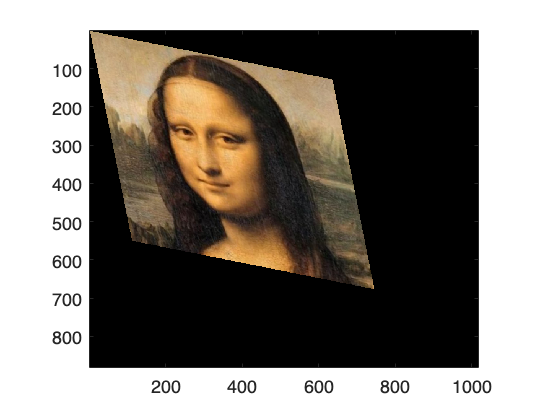

% An affine transformation basically preserves parallel lines and ratios 
% of distances between points. 
% 
% The matrix A written as A = U * Σ * V,
%
% U:    rotation matrix
% Σ:    scaling matrix
% V:    rotation matrix
%
% Every matrix performs an action on the image. So what essentially happens is that the affine transformation first
% rotates the image according to matrix U, then it scales this rotated
% image acording to Σ and finaly rotates this image with V.
% The final transformation is the same as an affine transformation
% 
% First, rotate the image with a matrix U so that the diagonal of the image
% becomes parallel (tangent) with the x-axis. Thereafter apply the scaling
% matrix Σ which is diag([k 1]) to stretch it along the x axis (which now is the diagonal)
% Finally, rotate back the scaled image with V to its orignal.
% et voilá we have stretched the image along its diagonal.


% Here is an example of how it works

% Read image of Mona
img = imread('./data/mona.png'); 
k = 1.5;

% Matrices U, Σ and V
U = [cos(pi / 4) -sin(pi / 4); sin(pi / 4) cos(pi / 4)];
SIGMA = diag([k,1]);
V  = [cos(pi / 4) -sin(pi / 4); sin(pi / 4) cos(pi / 4)]';

% Total affine transformation
A = (U*SIGMA*V);

% Show final stretched image
stretched = affine_warp(size(img).*2, img, A, [0;0]);
figure()
imagesc(stretched); axis image




% EDIT FOR RESUBMISSION
% I removed the part with the shear transformation. This was a mistake on
% my part. That section was the first thing I wrote and should've been
% removed before submitting the first time.

% / Nicholas Granlund


## Ex 3.2 Minimum correspondences

What is the minimal number of point correspondences, K, required in order to estimate an affine transformation between two images?

**Your answer here with explanation as a comment here.	**	

% K = 3
% 
% Since an affine transformation of a 2d image has 6 DoF,
% the number of point correspondences must be atleast 3 to be able to
% estimate the transformation.

% We basically have 6 parameters that needs solving for an estimation
% of the affine transformation. a,b,c,d tx and ty. 6 unknowns needs 6
% equations. And by pairing 3 point correspondences from 2 images, we are
% able to solve for the transformation parameters. Fewer than K=3 cannot
% solve.

% In essence, the minimal amount of data to estimate is 3 corresponding
% points from two images.

In general, an estimation problem where the minimal of amount of data is used to estimate the unknown parameters is called **a minimal problem**.

Once you have found a proper coordinate transformation between two images, you can use the provided function affine_warp to warp the source image and create a warped image. Let’s try it. 

## Ex 3.3 Trying warping

Load the image mona.png to the variable img. Try running the following code snippet :

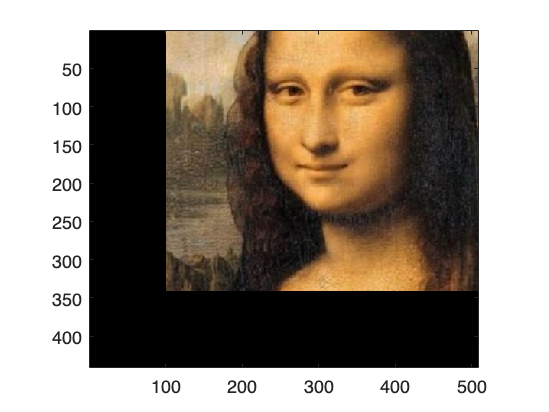

img = imread('data/mona.png'); 
A = [0.88 -0.48; 0.48 0.88];
A = eye(2,2);
t = [100;-100];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;			

Change the values in A and t to see what happens. First, swap A for eye(2,2) to try a pure translation and plot the result. Then, swap A and t for a stretching along a diagonal as in Ex 3.1 but without rotating and translating the image. Plot the result.

% Your Code here
A = eye(2,2);       % no altering
t = [100;-100];     % pure translation
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;

Explain what you observe in the two cases. **Write your answer as a comment here.**

% For the case when the transformation is purely translational. The picture
% of Mona only moves on the x-y plane. The entire image is shifted to the
% right 100 pixels and it is also raised by -100 pixels. This essentialy
% cuts out a chunk of the picture since it stops at her forehead.

% For the case of a diagonal stretching, please see the image in ex 3.1
% Here we can se that the image has been stretched along its diagonal. How
% this works is explained in 3.1. When there is no translation, the image
% upper left corner will stick to the origin but the lower right will be
% pulled away along the diagonal. 

## Ex 3.4 Writing test case				

For any estimation task it is a good idea to have at least one test case where you know what the answer should be. In this exercise you should make such a test case for RANSAC. Start by generating random points, `pts`, and a random transformation. Then transform these points to create a `pts_tilde`. If you want to make it more realistic, add random noise to the points. You now have two sets of points related by a known affine transformation as in *Ex 3.2*. In the following exercises you will try to estimate this transformation. As you know the correct answer it is easy to detect if you make a mistake. 					

**Make a function** 

that generates a test case for estimating an affine transformation. The transformation should map `pts` to `pts_tilde.` Don't add any outliers now. Outputs `pts` and `pts_tilde` should be `2 x N-arrays`. Also output the *true* transformation, so you know what to expect from your code.

After you have written the function, test it with a few runs here :

% Your code here

% Try it some times to make sure it works...
for i=1:6
    % Call function
    [pts, pts_tilde, A_true, t_true] = affine_test_case();

    % Determine mean residual
    res = mean( ((A_true) * pts + t_true) - pts_tilde , 'all');

    % Print information
    fprintf('TEST %.0f:  Mean error in estimation of affine: %.2f \n',i,res)

end

TEST 1:  Mean error in estimation of affine: 0.00 
TEST 2:  Mean error in estimation of affine: 0.00 
TEST 3:  Mean error in estimation of affine: 0.00 
TEST 4:  Mean error in estimation of affine: 0.00 
TEST 5:  Mean error in estimation of affine: 0.00 
TEST 6:  Mean error in estimation of affine: 0.00 



% seems to work just fine!

## Ex 3.5 Writing a minimal solver

Make a minimal solver for the case of affine transformation estimation. In other words, **make a function**

that estimates an affine transformation mapping `pts` to `pts_tilde`, where `pts` and `pts_tilde` are `2 x K - arrays` and `K` is the number you found in *Ex 3.2*. Try your function on points from the test case in *Ex 3.4*.

% Your code here

% Call function
[A, t] = estimate_affine(pts, pts_tilde);

% Determine mean residual
res = mean(((A*pts) + t) - pts_tilde,'all')

res = 1.7297e-15


% Works rather well...


## Ex 3.6 Computing residuals

Make a function

that computes the lengths of 2D residual vectors. The function should return an array with N values. *Hint : *Given a `2 x N` matrix, stored in `M`, the column-wise sum of the **squared** elements can be computed as `sum(M.^2, 1)`.

**Verify** that for no outliers and no noise, you get zero residual lengths given the true transformation:

% Your code here

% In the case of no outliers
% perform boolean test to see that we get zero residuals
zero_residuals = all(residual_lgths(A, t, pts, pts_tilde) == 0)

zero_residuals = logical
   1



% true!



% EDIT FOR RESUBMISSION
% I now changed the function from any() to all() to perform the correct boolean test. 
% Thank you for enlighten me about this.

% / Nicholas Granlund


## **Ex 3.7 Test case with outliers**

Modify your function `affine_test_case `to create a new function `affine_test_case_outlier `that takes a parameter `outlier_rate` and produces a fraction of outliers among the output points. For example, if `outlier_rate` is 0.2, then 80% of the samples will be related by `pts_tilde = A_true * pts + t_true`. While for the remaining 20%, pts_tilde can be distributed uniformly within some range. 

**Test your code here:**

% Your code here

% Lets try with some different outlier ratios.

for outlier_rate = [0  0.2  0.4  0.8]
    % Generate affine transformation
    [pts, pts_tilde, A_true, t_true] = affine_test_case_outlier(outlier_rate);

    % check that the quotien of inliers/outliers is corect
    outliers_percent = nnz(residual_lgths(A_true, t_true, pts, pts_tilde))/100
end

outliers_percent = 0

outliers_percent = 0.1900

outliers_percent = 0.3100

outliers_percent = 0.4800


% Since the outliers are uniformly distributed, they may still end up as an
% inlier Therefor the quotient may be lower than outlier_rate...

## **Ex 3.8 Writing a RANSAC based solver**

Make a function					

that uses RANSAC to find an affine transformation between two sets of points. (Like before the transformation should map `pts` to `pts_tilde`.) Test your function on test cases generated with your function `affine_test_case_outlier`. 

**RANSAC Note** : You can use the notes to decide on the number of RANSAC iterations needed given your required confidence and estimated inlier ratio. You can also use fixed iterations but make sure that you have enough iterations to find a reasonable solution.

**Verify your code here**. Try different outlier rates. Make sure that you get the right transformation for a reasonable outlier rate as well. 

% Your code here
% Threshold
threshold = 0.01;

% Lets try with some different outlier ratios.
for outlier_rate = [0  0.2  0.4  0.8]

    % Generate affine transformation
    [pts, pts_tilde, ~, ~] = affine_test_case_outlier(outlier_rate);
   
    % Call function
    [A,t] = ransac_fit_affine(pts, pts_tilde, threshold);

    % Check how many are outliers
    outliers_percent = nnz(residual_lgths(A, t, pts, pts_tilde))/100
 
end

RANSAC iterations done!
It took k=1 iterations to terminate...
Residual: 0.00 
Number of inliers: 100 


outliers_percent = 0

RANSAC iterations done!
It took k=4 iterations to terminate...
Residual: 8.62 
Number of inliers: 82 


outliers_percent = 0.1800

RANSAC iterations done!
It took k=9 iterations to terminate...
Residual: 10.96 
Number of inliers: 66 


outliers_percent = 0.3500

RANSAC iterations done!
It took k=19 iterations to terminate...
Residual: 8.49 
Number of inliers: 53 


outliers_percent = 0.4700




% EDIT FOR RESUBMISSION
% I now have altered the code so it performs some more tests in different
% outlier ratios. Also I need to emphasise that since the outliers are
% randomly distributed in the range, they may still end up as an inlier.
% For higher outlier_rate, more of these outliers may end up in the range
% as an inlier and therefor the actual outlier_rate is lower. However these
% outliers are still not related by pts_tilde = A*pts + t.

% / Nicholas Granlund

## Ex 3.9 Aligning images

For this exercise, you should use the function

in a similar way as in *Lab 1* to extract SIFT features. Note that it only works for grayscale images, so if you have a colour image you need to convert it to grayscale before with `rgb2gray`. To match features you can use the built-in function matchFeatures. To use the Lowe criterion (with threshold 0.8) you should use the following options: 

**Write a function:**

            warped = align_images(source, target, thresh) 

that uses SIFT and RANSAC to align the `source` image to the `target` image with `thresh` as the residual threshold for counting inliers in your RANSAC. To perform the actual warping, use the `affine_warp` function within your `align_images` function. Be very careful about the order in which you send the points to RANSAC. You can visualize your correspondences with **showMatchedFeatures**.

**Align **`vermeer_source.png` to `vermeer_target.png using` your `align_images` function. Plot the source, target and warped source images together.

% Your code here
source = rgb2gray(imread('./data/vermeer_source.png'));
target = rgb2gray(imread('./data/vermeer_target.png'));
thresh = 30;

warped = align_images(source, target, thresh); 

RANSAC iterations done!
It took k=229 iterations to terminate...
Residual: 1463639.27 
Number of inliers: 357 


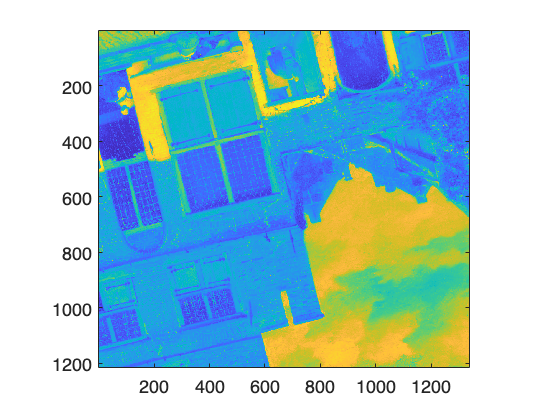


% You can use the following code snippet to plot images next to each other. You can also plot them in more appealing ways.
figure
imagesc(source);axis image

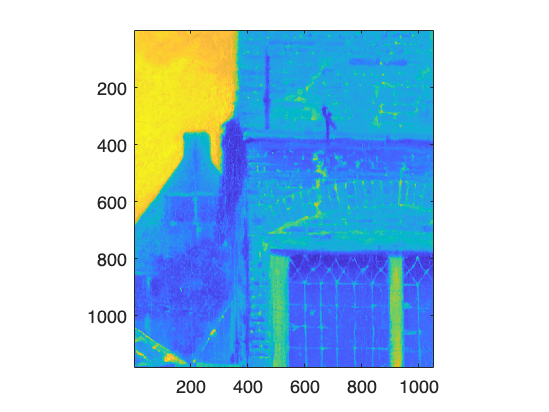

figure
imagesc(warped);axis image

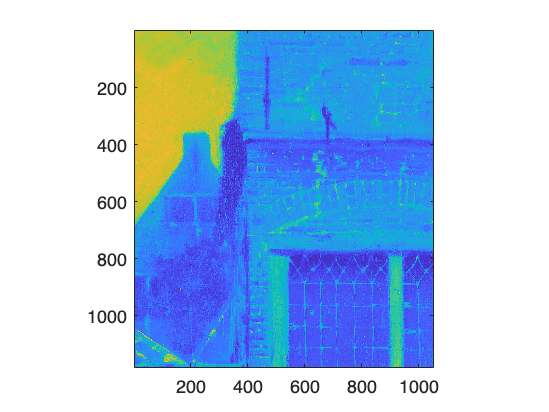

figure
imagesc(target);axis image

## Ex 3.10 Aligning images with known orientation

Medical images often have less local structure, making SIFT matching more difficult. It often works better if we drop the rotation invariance. The provided feature extraction function has an option for this. 

assumes that the image has a default orientation. Plot the warped and the target images next to each other to verify your result. Modify your `align_images` function to create function `align_images_v2 `so that it also takes a boolean argument, `upright` stating whether the images have the same orientation, i.e. 

Try aligning the images *CT_1.jpg* and *CT_2.jpg*. Try with and without rotation invariance and try different outlier thresholds. If you are still not successful, try the alternative descriptor SURF which is also implemented in MATLAB with

Also plot the warped image and the target image next to each other so one can verify the result (if successful).

% Your code here
source = imread('./data/CT_1.jpg');
target = imread('./data/CT_2.jpg');
thresh = 70;

warped = align_images_v2(source, target, thresh, true);

RANSAC iterations done!
It took k=1875 iterations to terminate...
Residual: 149900.99 
Number of inliers: 9 


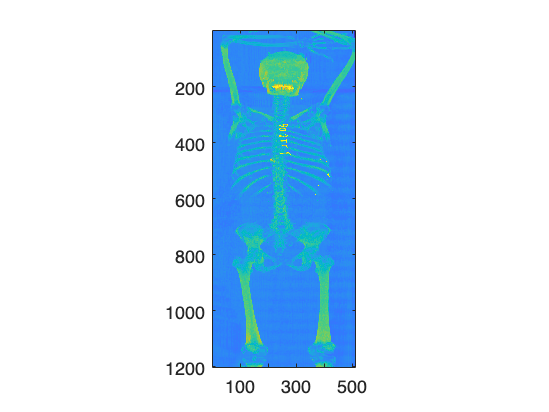


figure
imagesc(source);axis image

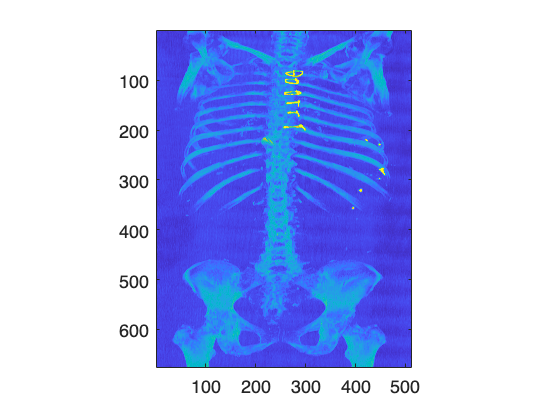

figure
imagesc(warped);axis image

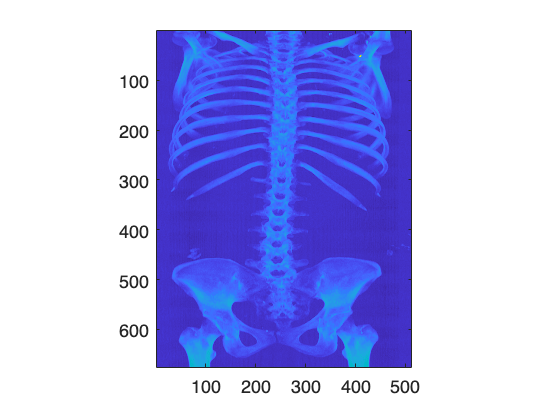

figure
imagesc(target);axis image

**Explain your observations of using and not using rotation invariance at different thresholds here.**

% For these particular images it was rather difficult to detect sift
% features...

% For upright = true
% When rotational invariance is neglected, it is much easier to align the
% images. For thresh=70 the results are repeatingly sucesfull. But for
% thresh=30, the algorithm has it much more difficult to allignt the
% images. And often the alignment is wrong. It also takes a bunch more
% iterations of the RANSAC to find the solution compared to the vermeer
% picture...

% For upright = false
% It seldom succeds to align the images. Sometimes it does't find a
% solution, and other times the solution is wrong. This is the case for any
% thresh... high threshold often gives wrong transformations


% Also notice hos few SIFT features we were able to detect since the
% amount of inliers for the best fit is only 9...

## Ex 3.11 Flouroscent image example (optional)

Try aligning *tissue_fluorescent.tif *and *tissue_brightfield.tif*. In the fluorescent image, the intensities are basically inverted, so you need to invert one of the images before computing descriptors. (Otherwise you won’t get any good matches.) You can invert it by taking 

Plot the warped image and the target image side by side so one can verify the result.

% Your code here
% rng(10)
% source = 255 - imread('./data/tissue_fluorescent.tif');
% target = rgb2gray(imread('./data/tissue_brightfield.tif'));
% 
% thresh = 30;
% 
% warped = align_images_v2(source, target, thresh, true);
% 
% figure
% imagesc(source);axis image
% figure
% imagesc(warped);axis image
% figure
% imagesc(target);axis image

% OBS
% This task was evidently more difficult than I anicipated. I couldn't manage
% to align the images in a meaningfull way...

Note that this example is optional due to the fact it may be hard to get good correspondences with MATLAB's implementation of SIFT.

# Warping

## Ex 3.12 Get pixel value

So far you have used Matlab's function for warping. The reason is that it is difficult to write a Matlab function for warping that is not painfully slow. Now you will get to write one anyway, but we will only use it for very small images. 

**Write a function**

that gives you the pixel value at `position`. If the elements of `position` are not integers, select the value at the closest pixel. If it is outside the image, return 1 (=white). Try your function on a simple image to make sure it works. 

% Your code here
simple_image = [1 2 3; 4 5 6; 7 8 9]

simple_image =      1     2     3
     4     5     6
     7     8     9



% Try exact position
value = sample_image_at(simple_image, [2 3]) 

value = 6


% Try outside of image
value = sample_image_at(simple_image, [-10 -4]) 

value = 1


% Try between pixels
value = sample_image_at(simple_image, [2.5 2.5])

value = 9

value = sample_image_at(simple_image, [2.4 2.4]) 

value = 5


% Seems to work fine!

## Ex 3.13 Warp

Now, you will do a warping function that warps a `16 x 16` image according to the coordinate transfomation provided in `transform_coordinates.m`. 

Write a function 

that warps source according to `transform_coordinates` and forms an output `16 X 16` image warped. Use your function `sample_image_at` to extract pixel values. Try the function on `source_16x16.tif` and plot the answer using imagesc. You will get to see a meaningful image if you get it right.

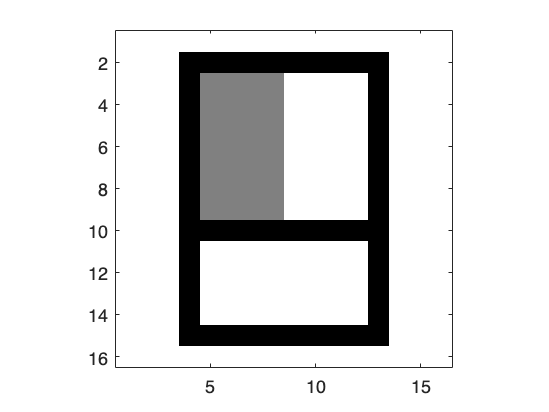

%Your code here
source = imread('./data/source_16x16.tif');
warped = warp_16x16(source);

figure
imagesc(source);axis image, colormap gray

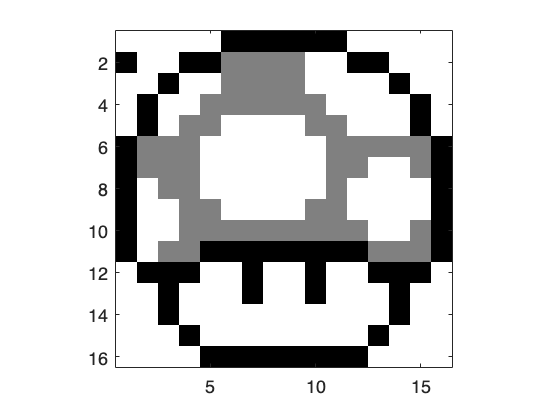

figure
imagesc(warped);axis image, colormap gray

# Least Squares

## Ex 3.14 LS

Write a function

that estimates an affine transformation mapping `pts` to `pts_tilde `in least squares sense, i.e., all points in `pts` and `pts_tilde` are used to compute the transformation. (Depending on how you wrote you estimate_affine.m, this might be very easy.) Use it on the inliers from RANSAC to refine the estimate. Add this to `align_images `to form a new function` align_images_inlier_ls` and test it on the `Vermeer` images for different outlier thresholds. Plot the final result images next to each other.

% Your code here
source = rgb2gray(imread('./data/vermeer_source.png'));
target = rgb2gray(imread('./data/vermeer_target.png'));

% My initial implementation of estimate_affine() is implemented in LS
% means. It considers all points and solves for the parameters param = M\x
% in the least squares sense... 

% lets try the Vermeer picture for different thresholds.
warped = {};
warped_ls = {};
i = 0;

for threshold = [10,30,70,100]
    % info
    i = i+1;
    fprintf('\n\n\nAligning images with threshold=%.0f...',threshold)

    % align images regularly
    warped{i} = align_images_v2(source, target, threshold, false);

    % align images and apply LS to inliers to refine estimation
    warped_ls{i} = align_images_inlier_ls(source, target, threshold, false);
end




Aligning images with threshold=10...

RANSAC iterations done!
It took k=24729 iterations to terminate...
Residual: 1884042.48 
Number of inliers: 19 


RANSAC with LS iterations done!
It took k=151 iterations to terminate...
Residual: 1462203.52 
Number of inliers: 358 









Aligning images with threshold=30...

RANSAC iterations done!
It took k=14516 iterations to terminate...
Residual: 1873962.27 
Number of inliers: 27 


RANSAC with LS iterations done!
It took k=142 iterations to terminate...
Residual: 1462558.50 
Number of inliers: 365 









Aligning images with threshold=70...

RANSAC iterations done!
It took k=9650 iterations to terminate...
Residual: 1853779.40 
Number of inliers: 26 


RANSAC with LS iterations done!
It took k=138 iterations to terminate...
Residual: 1450878.69 
Number of inliers: 369 









Aligning images with threshold=100...

RANSAC iterations done!
It took k=9650 iterations to terminate...
Residual: 1861087.78 
Number of inliers: 26 


RANSAC with LS iterations done!
It took k=136 iterations to terminate...
Residual: 1461380.70 
Number of inliers: 371 






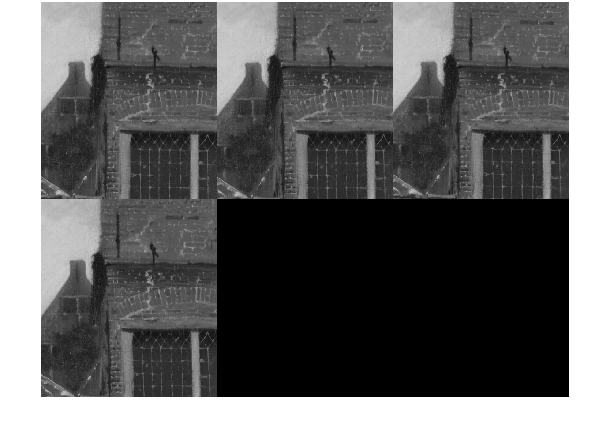


figure()
montage(warped)

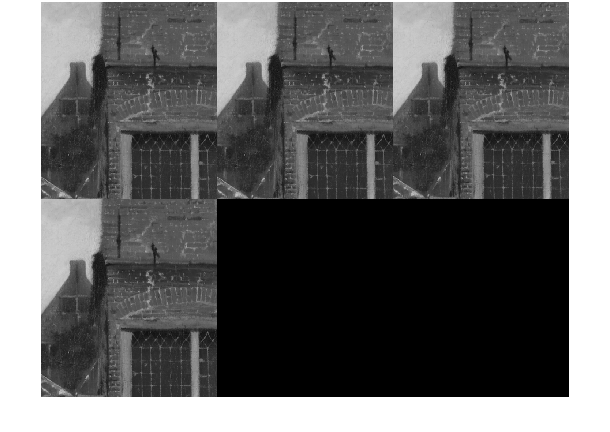

figure()
montage(warped_ls)





% EDIT FOR RESUBMISSION
% I have know ensured that the LS is applied to the inliers. I did this by
% creating a function ransac_fit_affine_ls() which is similar to
% ransac_fit_affine(), but applies LS on the inliers to refine the affine
% estimation. I also edited my observations since LS seems to improve the
% performance significantly... see below.

% / Nicholas Granlund

Do you notice an improvement? Observe visually and also in terms of the residuals. **Explain your observations and the plausible reasons behind them as comment here.**

% There is noticable improvement when using LS on the inliers.

% First of all, the amount of iterations of the RANSAC to find a
% good fit are fewer when using LS on inliers. for example with
% threshold=10 we get that for LS it takes k=152 to find a good fit. 
% But when we dont use LS on the inliers, it instead takes k=15929
% iterations to find a good fit.

% Secondly, the affine estimation is better itself since the residual is
% smaller. for example the LS gives a residual of ≈1462000 and without LS
% we instead get ≈1863000

% Thirdly, the LS seems to find solutions for both lower and higher values
% for thresholds whereas the counterpart does not. LS also contains way
% more inliers...

% A plausable reason for this is that initially, random sift features (or just points)
% are selected throughout the picture which an estimation is performed on.
% The problem here is that it may be difficult to find a good fit if
% the randomly picked points are to scattered.. By taking this estimation and 
% refining it by trying to fit it better to the inliers, we discard many
% points that are outside the threshold. We are essentially not performing
% an affine estimation on a picture any longer, but an affine estimation on
% a line with the width given by the variable "threshold" (so just a slice of the picture). 
% This means that the outliers (the rest of the picture) dont influence the refined
% estimation! They instead only acts as a good starting point.

% I find the above to be somewhat difficult to explain, but I hope it makes sense for
% the examiner

% Applying LS to the inliers seems to be a good idea to improve the
% performance of the affine estimator.

% Nevertheless, by observing the pictures there is no difference
% whatsoever that one may spot by just visuall examination.
